# **How to correct errors in port width or dimension in simulink?**

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_09_04_Challenges/2024_09_04_PropagationChallenges.prj)

Let's continue our tour of the most viewed Simulink-related MATLAB Answers. This week, we look at:

[**How to correct error in port width or dimension in simulink ?**](https://www.mathworks.com/matlabcentral/answers/405908-how-to-correct-error-in-port-width-or-dimension-in-simulink)

While this error mentions dimensions, the same principles and techniques to debug this error apply also to other properties like data types and sample times.

## The Problem

To begin, let's recreate a model similar to the one in the [MATLAB Answers post](https://www.mathworks.com/matlabcentral/answers/405908-how-to-correct-error-in-port-width-or-dimension-in-simulink):

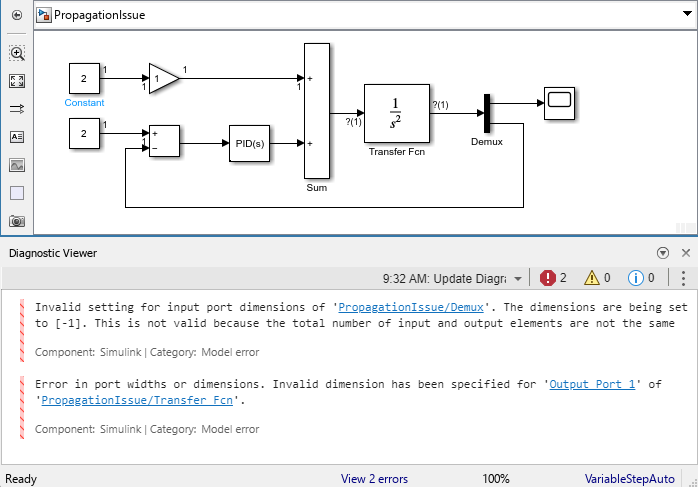

mdl = "PropagationIssue";
out = sim(mdl,"CaptureErrors","on");
out.ErrorMessage

ans =     'Error due to multiple causes.
     Caused by:
         Invalid setting for input port dimensions of 'PropagationIssue/Demux'. The dimensions are being set to [-1]. This is not valid because the total number of input and output elements are not the same
         Error in port widths or dimensions. Invalid dimension has been specified for 'Output Port 1' of 'PropagationIssue/Transfer Fcn'.'


## A First Solution

In this specific model, my best guess is that the user thought that they had to use a [Demux](https://www.mathworks.com/help/releases/R2024a/simulink/slref/demux.html) block to send a signal to two destinations. The simplest way to fix this model is to get rid of the Demux block and simply branch the signal. To branch a signal, you can right-click on it and drag.

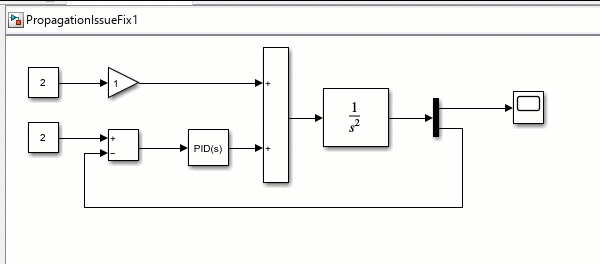

While this model is easy to fix, getting this error in a more complex model can be challenging. Let's see how I typically debug this error.

## Debugging Tips

When running into propagation errors, there are typically two blocks reported: The source and the destination. In this case we have:

- `Invalid setting for input port dimensions of '`[`PropagationIssue/Demux`](matlab:open_and_hilite_hyperlink ('PropagationIssue/Demux','error'))`'`

- `Invalid dimension has been specified for '`[`Output Port 1`](matlab:slprivate('open_and_hilite_port_hyperlink', 'hilite', ['PropagationIssue/Transfer Fcn'], 'Outport', 1);)`' of '`[`PropagationIssue/Transfer Fcn`](matlab:open_and_hilite_hyperlink ('PropagationIssue/Transfer Fcn','error'))`'`

The error happens because there is a disagreement between those two blocks.

When initializing a model, Simulink interrogates each block to determine if their ports must have a specific dimension, or if they can inherit it. If they can inherit a dimension, Simulink will propose a value based on the upstream or downstream blocks and the block will respond to let Simulink know if it can accept the proposed dimension.

Here is how I picture this negotiation:

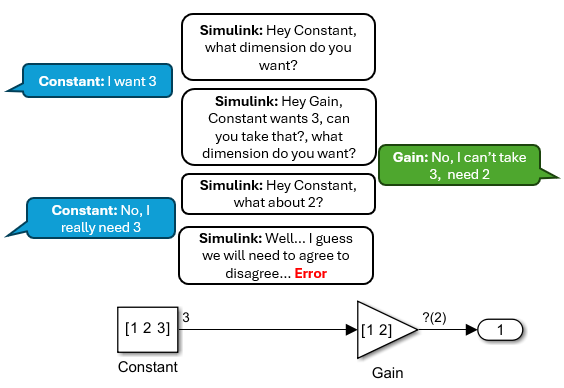

### Display Signal Dimensions

When debugging dimension issues, I recommend enabling "[Signal Dimensions](https://www.mathworks.com/help/releases/R2024a/simulink/ug/displaying-signal-properties.html#f15-90115)" and "[Nonscalar Signals](https://www.mathworks.com/help/releases/R2024a/simulink/ug/displaying-signal-properties.html#f15-90108)" from the "Information Overlays"

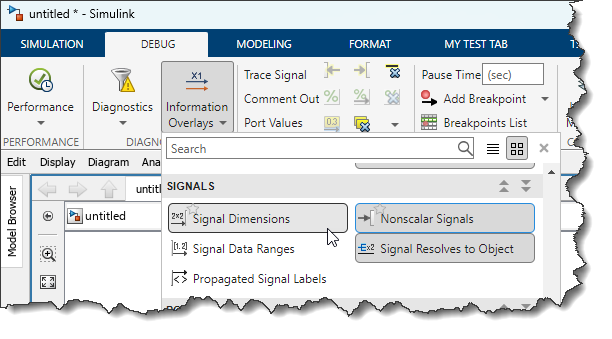

Then I like to try the following two options.

#### Option 1: Ground and Terminators 

By disconnecting the two problematic blocks, you might be able to get a successful update diagram (`Ctrl+D`) and see which dimensions Simulink is trying to propagate on each side. In this case, we can see that the [Transfer Function](https://www.mathworks.com/help/releases/R2024a/simulink/slref/transferfcn.html) wants to output a dimension of 1, while the [Demux](https://www.mathworks.com/help/releases/R2024a/simulink/slref/demux.html) wants a dimension of 2:

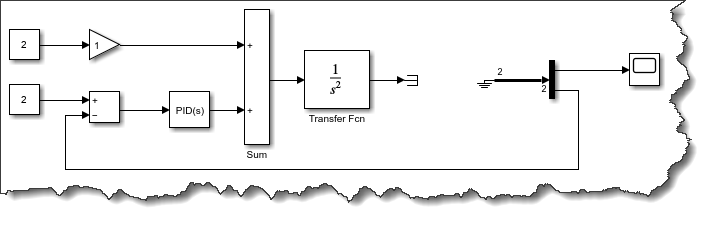

#### Option 2: Signal Specification

When I know what the dimension should be, I like to try inserting a [Signal Specification](https://www.mathworks.com/help/releases/R2024a/simulink/slref/signalspecification.html) block and specifying the known dimension. In this negotiation between Simulink and all the blocks, the Signal Specification enforces the dimension of the signal, which usually helps getting a clearer error. At a minimum, it should help you determine which one of the two conflicting ports is trying to propagate the unexpected dimension.

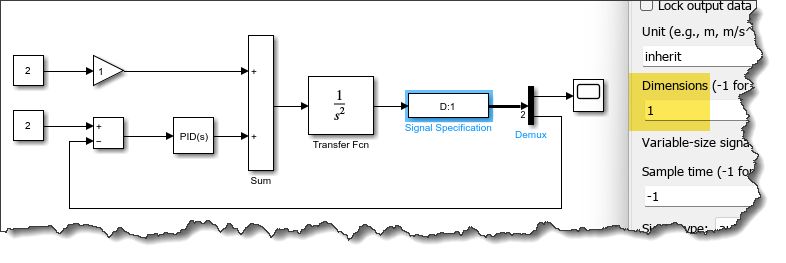

With those two techniques, I usually get the information I need to understand what I did wrong and modify the model to resolve the error.

## The Demux block

There is another part to the error, specific to the Demux block:

- `The dimensions are being set to [-1]. This is not valid because the total number of input and output elements are not the same`

Let's dissect this.

### [-1]

In Simulink, the value of "-1" for most properties usually means "inherited". For example, if you drag an Inport block in a model, the default value for Port dimensions is set ot "-1":

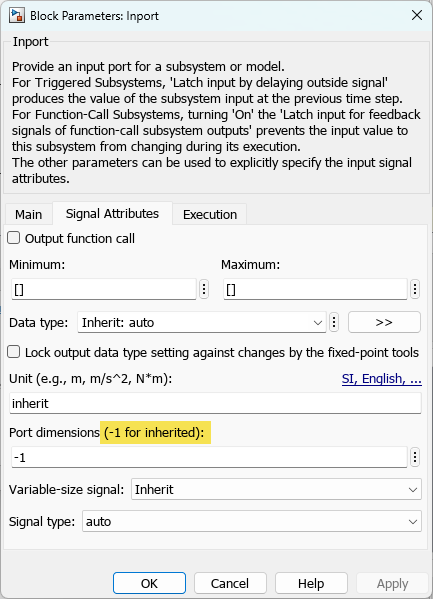

### Demux Specification

As mentioned in its dialog, the Demux block can be used to split vector signals into scalars or smaller vectors. The thing to realize is that it can be configured in two ways.

#### Option 1: Number of Ports

In that case, Simulink will try to evenly spread the incoming vector among the number of specific ports. In this example, we receive 5 and split it in 3 and 2:

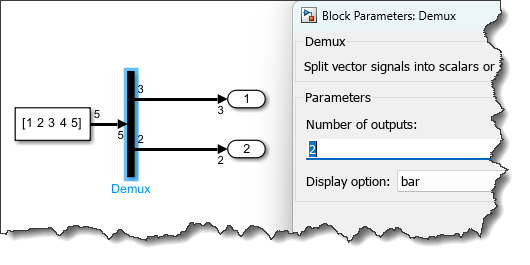

When the block is configured that way, it's like saying that the dimension of the individual ports is set to "-1".

#### Option 2: Dimension per ports

If I want two ports, but split the vector of 5 into 4 and 1, I can specify that as a vector where the number of elements is the number of ports:

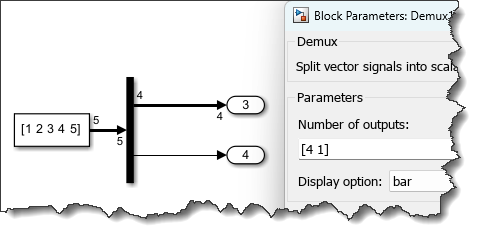

With all that being said, because of the feedback loop in the original model, what the Demux block is trying to say through this error is that the only way the model could update is if the dimension of its input signal is the same as its output.

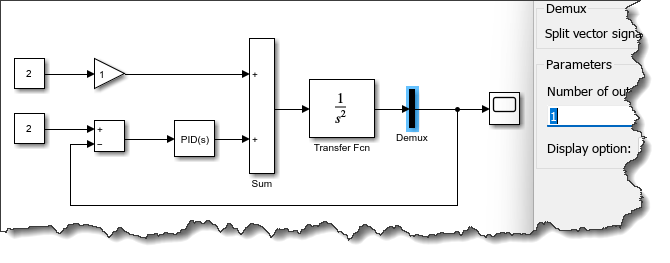

## Now it's your turn

Do you have tips and tricks for debugging dimensions proprapagation issues in Simulink? Let us know in the comments below.